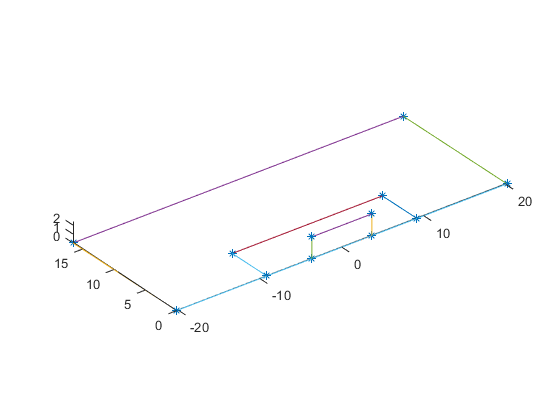

close all;
clear;
clc;


%load and draw image
im=imread('goal_picture.jpg');
figure(1);clf;image(im);hold on;


%% Real world 3D coordinates (according to soccer field dimensions):

% the soccer goal is 7.32m wide and 2.44m high:
x = 7.32/2;
z = 2.44;
goalframe = [-x x x -x;0 0 0 0;0 0 z z;1 1 1 1];

% the target area is 11 + 7.32m wide and 5.5m deep
xx = 18.32/2;
yy = 5.5;
innerframe = [-xx -xx xx xx;0 yy yy 0;0 0 0 0;1 1 1 1];

% the penalty area is 40.32 m wide and 16.5 m deep
xxx = 40.32/2;
yyy = 16.5;
outerframe = [-xxx -xxx xxx xxx;0 yyy yyy 0;0 0 0 0;1 1 1 1];

pts3d=[goalframe,innerframe,outerframe];

figure(2);clf;
plot3(pts3d(1,:),pts3d(2,:),pts3d(3,:),'*');
hold on;axis equal;rotate3d on;

%draw frames
for ii=1:3
    for jj=1:4
        jjp=mod(jj,4)+1;
        index=[jj,jjp]+(ii-1)*4;
        plot3(pts3d(1,index),pts3d(2,index),pts3d(3,index),'-');
    end
end

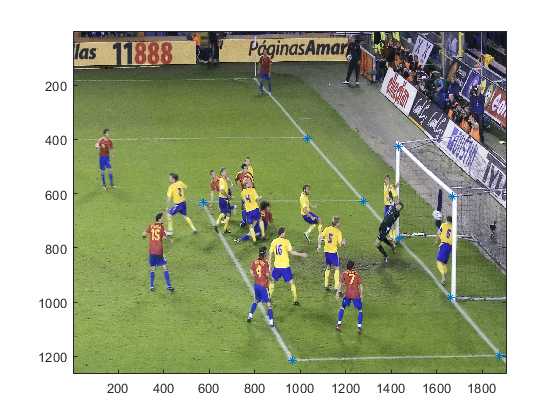

  
%% Image 2D coordinates:

%2d points in the image. (Some of the corresponding points are not visible in the image and are therefore set
%to NAN. These points cannot be used for estimating the camera matrix).
pts2d = 1e3*[
    1.6610    1.4366    1.4323    1.6698    1.8765 0.9660    0.5745    1.2783       NaN       NaN NaN    1.0320
    0.9818    0.7637    0.4274    0.6122    1.1961 1.2146    0.6343    0.6270       NaN       NaN NaN    0.3978
    0.0010    0.0010    0.0010    0.0010    0.0010 0.0010    0.0010    0.0010       NaN       NaN NaN    0.0010 ];

figure(1);
plot(pts2d(1,:),pts2d(2,:),'*');  

## Question 4

## Part a

A = zeros(18,12); % Building A matrix
k=0;
% Each 3d and 2d points creates 2 rows in the matrix as we saw in the
% tutorial
for i = 1:12 
    % nan points are useless for the algorithem so we skip them
    if (isnan(pts2d(1,i)))
        k = k + 1;
        continue;
    end
    j = 2 * (i-k) - 1;
    A(j, :) = [-pts3d(:,i)', zeros(1,4), pts2d(1,i) * pts3d(:,i)']; 
    A(j + 1, :) = [zeros(1,4), -pts3d(:,i)', pts2d(2,i) * pts3d(:,i)'];
end
% Using SVD decomposition to get V (right eigenvectors matrix)
[U,S,V] = svd(A); 

% the last column of V is the eigen vector that corresponds to the smallest
% eigen value so it minimize ||Am|| (as m)
M = V(:,12);
% Reshape the vector to fit matrix form
M = reshape(M, [4,3]).';


## Part b

% In order to project we use the relation of x'=MX
reprojected2d = M * pts3d;
% dividing by the last paramter to get x,y
reprojected2d = reprojected2d ./ reprojected2d(3,:);

e = 0;
num = size(pts2d,2);
% Calculating each point distance from original point and sum 
for i = 1:num
    % Skip nan points
    if isnan(pts2d(1,i))
        continue;
    end
    e = e + norm(reprojected2d(:,i) - pts2d(:,i),2);
end
% Calculating average error
e = e / num;

e = 2.6422

## Part c

% M is equals to [KR|Kt]
KR = M(:, 1:3); 
% using the composition we were given to get K and R 
[K, R] = rq(KR);


## Part f

% Calculating translation vector 
t = inv(K) * M(:,4);
% Calculating camera position
X0 = -inv(R) * t;


## Part g

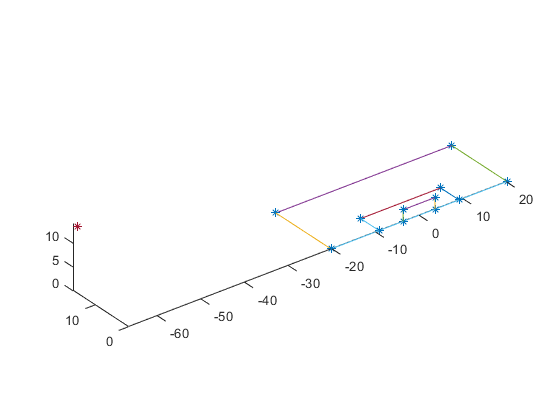

% Ploting camera position
figure(2);
plot3(X0(1), X0(2), X0(3), '*');